# Encoders

[Dataset] = load_dataset(0);

data = table2array(Dataset(:,1:end-1))

data =     0.0186    0.0055   -0.0018    0.1128    0.0636    0.0531   17.7348   23.5747   21.1154   10.4140  169.8634  135.1797    2.4464   68.0438   53.0663    0.0018    0.0079    0.0055
    0.0348    0.0354    0.0370    0.0556    0.0358    0.0301   30.4259   20.7144   31.9356   21.7924  196.1949  167.5661    6.6464   74.3810   48.4749    0.0007    0.0081    0.0083
    0.0137   -0.0007   -0.0033    0.0412    0.0198    0.0183   15.6440   31.4728   31.5458   17.5664  113.0512  181.1619    2.9674   41.0202   49.9472    0.0008    0.0037    0.0048
    0.0131    0.0450    0.0687    0.1202    0.1717    0.1950    7.1676   25.9207   15.6213   21.5404  124.0460  237.0935    4.7978   43.4408   98.5371    0.0010    0.0067    0.0084
    0.0472    0.0432    0.0380    0.1144    0.0673    0.0778   21.3845   18.8897   10.5423   27.4554  170.9747  185.8414    8.4086   68.9992   69.4436    0.0011    0.0062    0.0045
    0.0282    0.0909    0.1179    0.1053    0.0720    0.0593   17.8236   27.7842   22.50


Pos = data(1:20,:);
Neg = data(21:end,:);


## Positive

autoenc = trainAutoencoder(Pos',3);
P = encode(autoenc,Pos');


## Negative

autoenc = trainAutoencoder(Neg',3);
N = encode(autoenc,Neg');

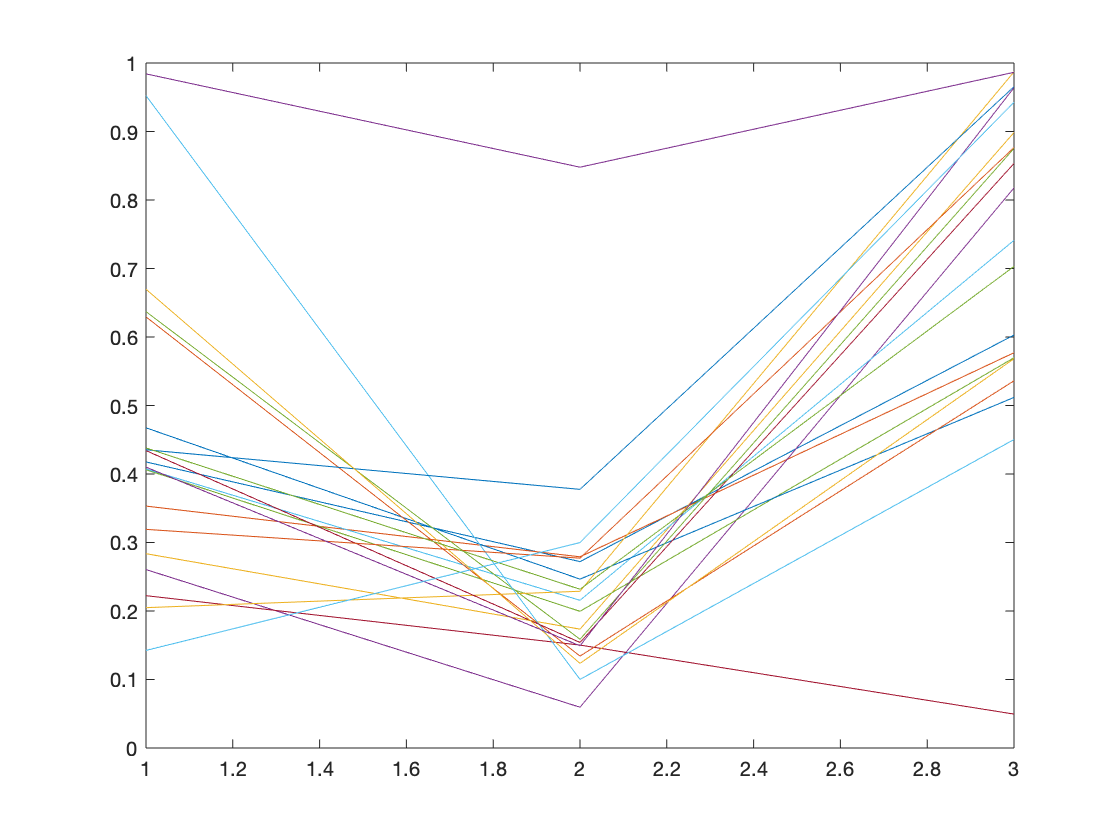

plot(P)

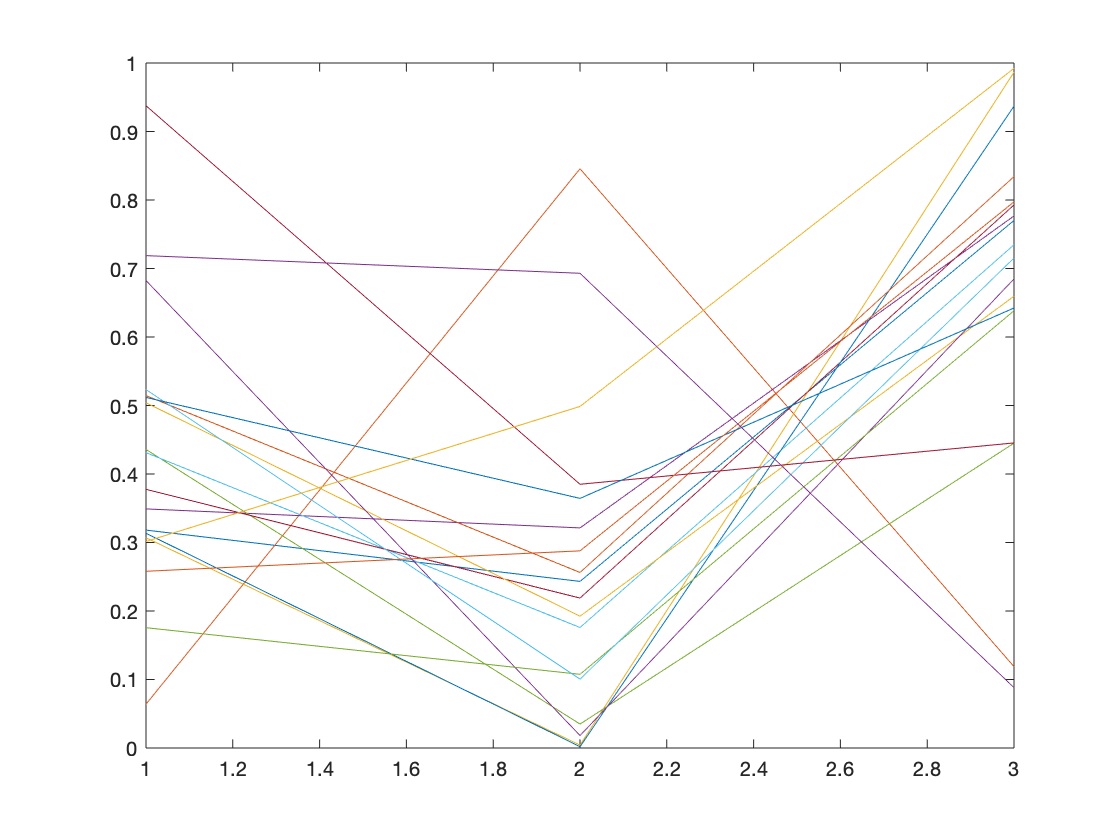



plot(N)